# Generalized negative binomial distribution

**Definition** [generalized negative binomial distribution]: Given $n$ coins with HEAD probabilities $$p_1, p_2, \dots, p_n$$, flip the coins one by one in this order. Let m be coins fliped when there are r HEADs. We say $m$ follows a generalized negative binomial distribution: $m \sim GNB(r, [p_1, p_2, \dots, p_n])$. 

What is the distribution of $m$, and what is the expectation of m? In this note, we simulate this process, and present a dynamic programming solution for the probability mass function. We also proposed three approximations and show how close they are from the true distribution. 

rng(20181106);
n = 3000;
num_r = 200;
pfrom = 'real';

if strcmp(pfrom, 'beta')
  % generate the probabilities 
  p = ones(1, n) * .01;
  p(1:n) = betarnd(5, 10, 1, n);
  % p(num_r*2+1:end) = rand(1, n-2*num_r) * .1;
elseif strcmp(pfrom, 'real')
  % probabilities from real data
  num_pos = 100;
  num_neg = 40;
  addpath(genpath('../../active_search'));  % change this accordingly
  addpath(genpath('../'));
  data_name = 'nips_data';
  [problem, labels, weights, alpha, nearest_neighbors, similarities] = ...
    load_data(data_name, 50, '../data/');
  model = get_model(@knn_model, weights, alpha);
  model = get_model(@model_memory_wrapper, model);
  positive_ind = find(labels == 1);
  negative_ind = find(labels == 2);
  train_ind = randsample(positive_ind, num_pos);
  train_ind = [train_ind; randsample(negative_ind, num_neg)];
  test_ind = unlabeled_random_selector1(problem, train_ind, n);
  probabilities = knn_model(problem, train_ind, labels(train_ind), ...
            test_ind, weights, alpha);
  p = probabilities(:,1)';
end

p = sort(p, 'descend');

plot(p(1:500))
xlabel('points')
ylabel('probabilities')

**Definition** [Generalized binomial distribution] Let there be $n$ different coins with HEAD probability $$p_1, p_2, \dots, p_n$$. We independently toss each coin once; we say the number of HEADs $r$ follows a generalized binomial distribution $GB(n, \{p_1, p_2, \cdots, p_n\})$. 

The probability mass function (PMF) of $r \sim GB(n, \{p_1, p_2, \cdots, p_n\})$ can be computed via dynamic programming:


$$
 {\textstyle	\Pr_{GB}(n, r) } = 
	\begin{cases}
		\prod_{i=1}^{n} (1- p_i), & \text{if } r = 0; \\
		p_n \Pr_{GB}(n-1, r-1)  + (1 - p_n) \Pr_{GB}(n-1, r), & \text{if } 0 < r <= n. \\
		0	& \text{if } r > n; \\
	\end{cases}
$$


Based on the PMF of GB, we can derive the PMF of GNB:


$$	{\textstyle \Pr_{GNB}(m, r)}
	= 
	\begin{cases}
		0, 	& \text{if } m < r; \\
		p_m \Pr_{GB}(m-1, r-1),  & \text{if } m \ge r.
	\end{cases}$$


[pgnb, pgb] = compute_generalized_negative_binomial_distribution_all(p, num_r);

% exactly compute the expectation 
m_expectation_true = nan(1, num_r);
for r = 2:num_r+1
  m_expectation_true(r-1) = sum(pgnb(r:n+1, r) .* (r-1:n)');
end

Use Monte carlo to estimate the expectation of $m$


num_sample_paths = 32768;
if exist('m_samples.mat', 'file') == 2
    load('m_samples');
else
    m_samples = nan(num_sample_paths, num_r);
    unif = rand(num_sample_paths, n);
    coin_heads = unif < p;
    num_heads = cumsum(coin_heads, 2);
    for r = 1:num_r
      for i = 1:num_sample_paths
        m_samples(i, r) = find(num_heads(i,:) >= r, 1);
      end
    end
end
m_expectation_monte_carlo = mean(m_samples);


Plot the GNB PMF: several examples

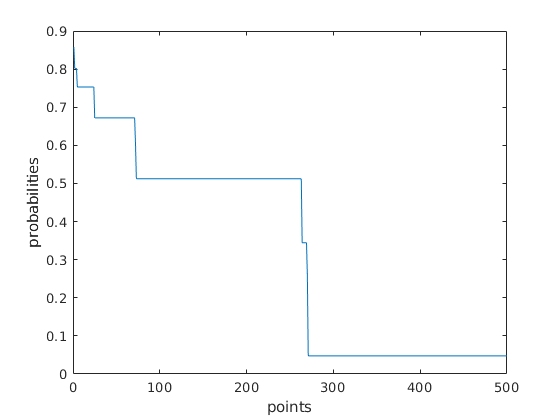

plot_r = [10, 20, 60, 100, 150, 200];
figure(1); hold on

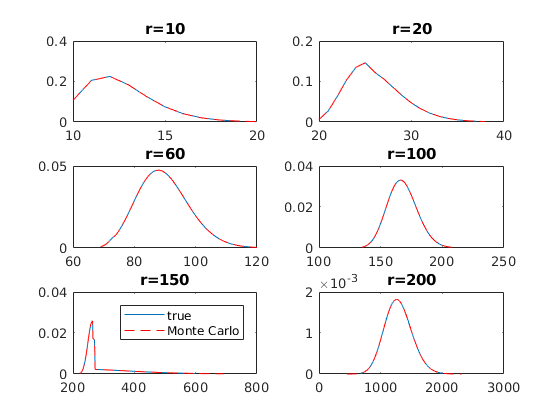

mm = 3;
nn = 2;
for i = 1:length(plot_r)
  subplot(mm, nn, i)
  max_prob = max(pgnb(1:n,plot_r(i)));
  plot_idx = find(pgnb(1:n, plot_r(i)) > max_prob*.01);
  plot(plot_idx, pgnb(plot_idx,plot_r(i)))
  
  freq = tabulate(m_samples(:, plot_r(i)));
  prob = freq(:,2) / sum(freq(:,2));
  subplot(mm, nn, i);
  hold on
  max_prob = max(prob);
  plot_idx = find(prob > max_prob*.01);
  plot(plot_idx, pgnb(plot_idx,plot_r(i)), 'r--')
  
  title(sprintf('r=%d', plot_r(i)))
  if i == 5
      legend('true', 'Monte Carlo')
  end
end

Another two heuristic approximations 

%% approximation 1
% 1/p1 + 1/p2 + ... + 1/pr
m_expectation_approx1 = cumsum(1./p(1:num_r));

%% approximation 2
m_expectation_approx2 = nan(1, num_r);
cumsum_p = cumsum(p);
for r = 1:num_r
  n_flips = find(cumsum_p >= r, 1);
  extra = (cumsum_p(n_flips) - r);
  n_flips = n_flips - extra / p(n_flips);
  m_expectation_approx2(r) = n_flips;
end

See how close these approximations are in terms of the expecation

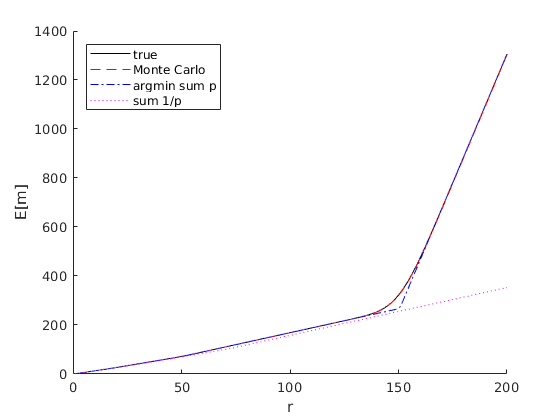

approx = [m_expectation_true; ...
          m_expectation_monte_carlo; ...
          m_expectation_approx2; ...
          m_expectation_approx1];
style = {'-k', '--r', '-.b', ':m'};
figure; 
hold on
for i = 1:4
  plot(1:num_r, approx(i,:), style{i});
end
xlabel('r')
ylabel('E[m]')
legend('true', 'Monte Carlo', 'argmin sum p', 'sum 1/p',  ...
  'location', 'northwest')


difference1 = m_expectation_true - [m_expectation_monte_carlo; ...
  m_expectation_approx2; m_expectation_approx1];
rmse1 = sqrt(mean(difference1.^2, 2))

rmse1 =     1.2832
   10.0602
  280.1071


Plot approximation error against the number of Monte Carlo samples 

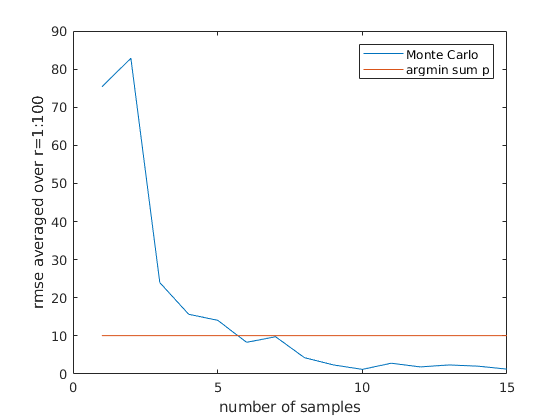

cum_mean = cumsum(m_samples)./ (1:num_sample_paths)';
difference = (m_expectation_true - cum_mean);
rmse = sqrt(mean(difference.^2, 2));
figure;
expo = 1:floor(log2(num_sample_paths));
plot_path = 2.^(expo);
plot(expo, rmse(plot_path))
hold on
plot(expo, ones(1,length(expo)) .* rmse1(2));
legend('Monte Carlo', 'argmin sum p');
xlabel('number of samples')
ylabel('rmse averaged over r=1:100');